clc; close all; clearvars;

% add paths
addpath('spotless/')
addpath('sedumi/')

% define van der pol eom
syms x_1 x_2 real

dot_x_1(x_1, x_2) = -x_2

$$dot\_x\_1(x\_1, x\_2) = -x_{2}$$

dot_x_2(x_1, x_2) = x_1 - (1 - x_1^2)*x_2

$$dot\_x\_2(x\_1, x\_2) = x_{1}+x_{2}\,\left({x_{1}}^{2}-1\right)$$

% linearize about the origin
x = [x_1, x_2]

$$x = \left(\begin{array}{cc} x_{1} & x_{2} \end{array}\right)$$

x_dot = [dot_x_1(x_1,x_2); dot_x_2(x_1,x_2)];
A = [
    jacobian(dot_x_1, x);
    jacobian(dot_x_2, x)
];

A =subs(A, [x_1, x_2], [0, 0])

$$A(x\_1, x\_2) = \left(\begin{array}{cc} 0 & -1\\ 1 & -1 \end{array}\right)$$


P = lyap(A' ,eye(2));
x = [x_1;x_2];
V(x)= x' * P * x;
V_dot(x) = 2 * x' * P * x_dot

$$V\_dot(x\_1, x\_2) = -x_{2}\,\left(3\,x_{1}-x_{2}\right)-\left(x_{1}-2\,x_{2}\right)\,\left(x_{1}+x_{2}\,\left({x_{1}}^{2}-1\right)\right)$$

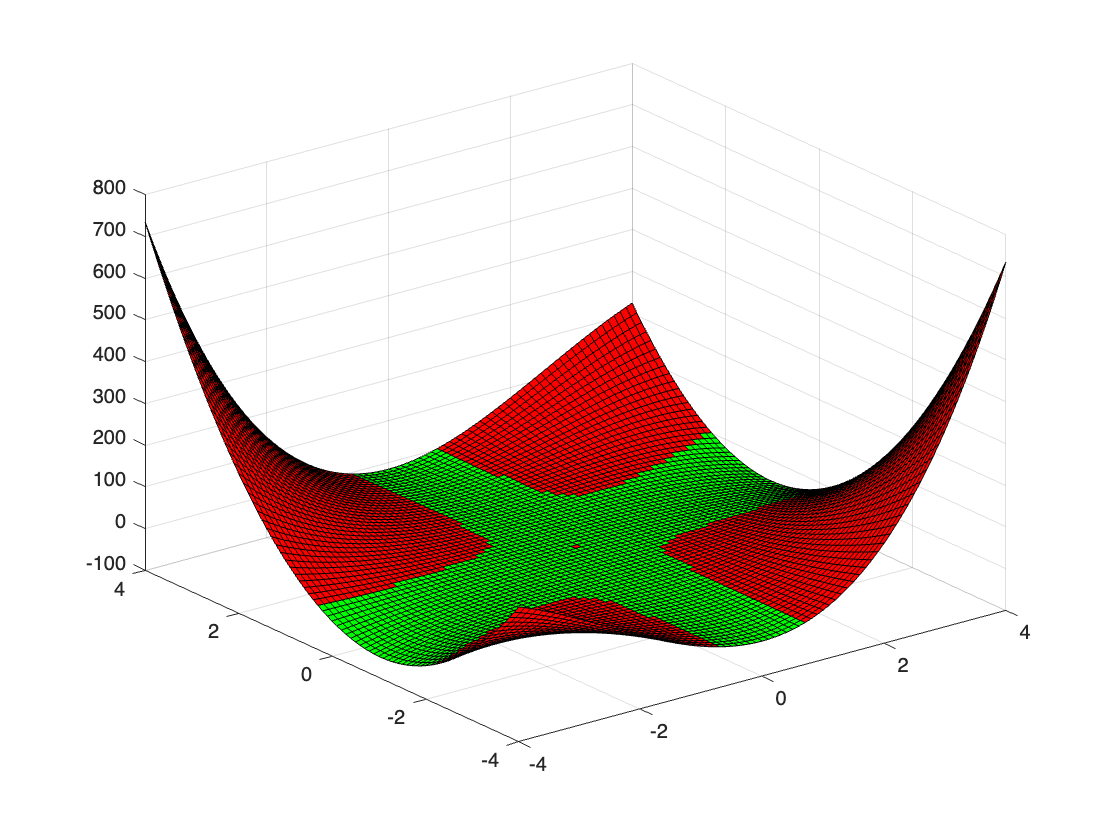

% quiver plot
region = -4:0.1:4;
[X1,X2] = meshgrid(region,region);

U = dot_x_1(X1,X2);
V = dot_x_2(X1,X2);

%quiver(X1, X2, U, V)

Z = [];
Z_color = [];

for i=1:size(X1,1)
    for j =1:size(X1,2)
        color = [1 0 0];
        Z(i,j) = V_dot(X1(i,j), X2(i,j));
        
        if Z(i,j)<0
            color = [0 1 0];
        end
        Z_color(i,j,[1:3]) = color;
    end
end


figure(1)
surf(X1, X2, Z, Z_color)

addpath('sedumi/')
addpath('spotless/')

% Define a polynomial 'x' with 2 indeterminates.
x = msspoly('x', 2);

Unrecognized function or variable 'mss_match'.

Error in msspoly.isName (line 221)
                    all(mss_match(msspoly.nameChars,ch)>0);

Error in msspoly (line 103)
                if ~msspoly.isName(x)


% Define a polynomial 'c' with 6 indeterminates.
c = msspoly('c', 6);

% Define a polynomial 'g'.
g = msspoly('g');

% Define a vector function 'f' with respect to 'x'.
f = [-x(2); x(1) + (x(1)^2 - 1) * x(2)];

% Define a 2x2 matrix 'P'.
P = [1.5 -0.5; -0.5 1];

% Compute the derivative of 'V' with respect to time using the dynamics 'f'.
Vdot = f' * P * x + x' * P * f;

% Define a Lyapunov function 'V' as a quadratic form in 'x'.
V = x' * P * x;

% Define a SOS polynomial 's' as a function of 'x' and coefficients 'c'.
s = c(1) * x(1)^2 + c(2) * x(1) * x(2) + c(3) * x(2)^2 + c(4) * x(1) + c(5) * x(2) + c(6);


for r=2:0.01:4
    % Define the SOS condition 'q' for the program.
    q = s * (V - r) - Vdot - g * (x' * x);
    % Initialize the sum of squares program.
    pr = mssprog;
    
    % Declare 'c' and 'g' as free variables in the SOS program.
    pr.free = c;
    pr.free = g;
    
    % Add the condition that 'q' should be a sum of squares in the program.
    pr.sos = q;
    
    % Set the objective of the SOS program to maximize 'g'.
    pr.sedumi = -g;

    out = pr({g});
    if out>0
        good_r = r;
    else
        break
    end
end

good_r

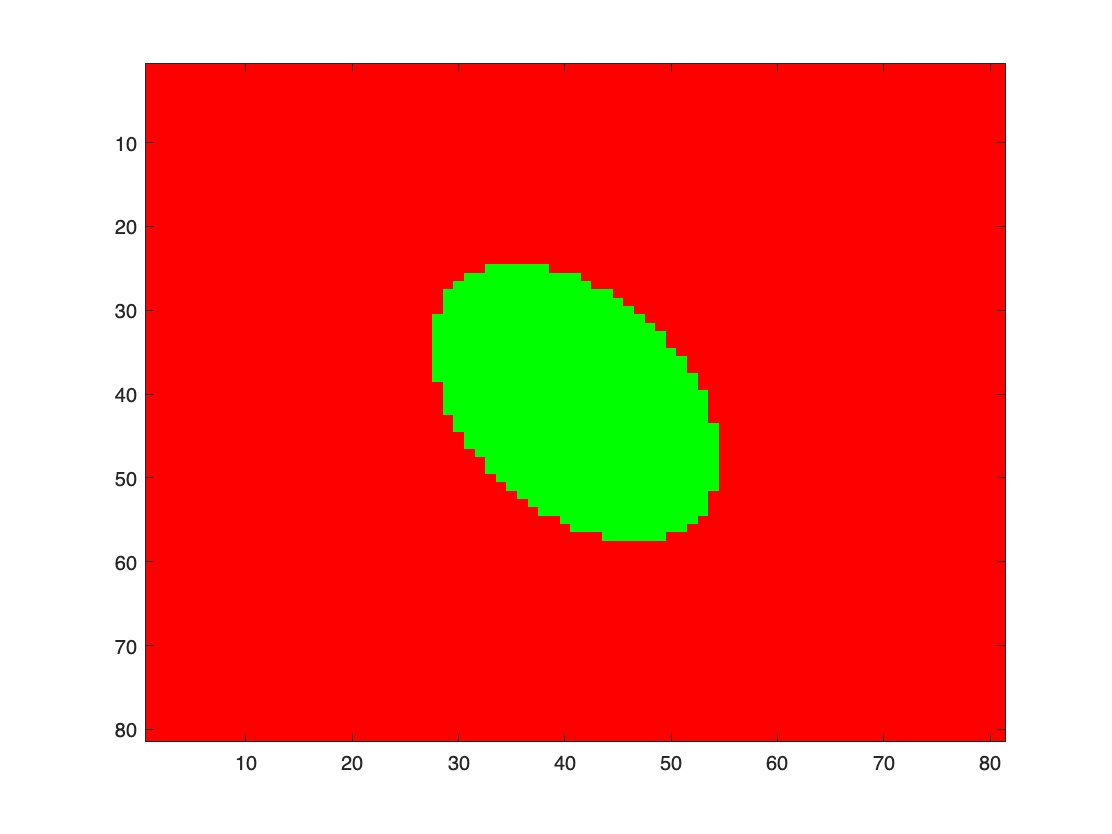

% plot where V(x) = good_r
clear V, x;
x= [x_1; x_2];

V(x) = x' * P * x;

Z= [];
Z_color = [];

for i=1:size(X1,1)
    for j=1:size(X1,2)
        color = [1 0 0];
        Z(i,j) = V(X1(i,j), X2(i,j));
        if Z(i,j)<good_r
            color = [0 1 0];
        end
        Z_color(i,j,[1:3]) = color;
    end
end 

image(Z_color)